## **Driver test program to check Clothoids library**

**Test circle**

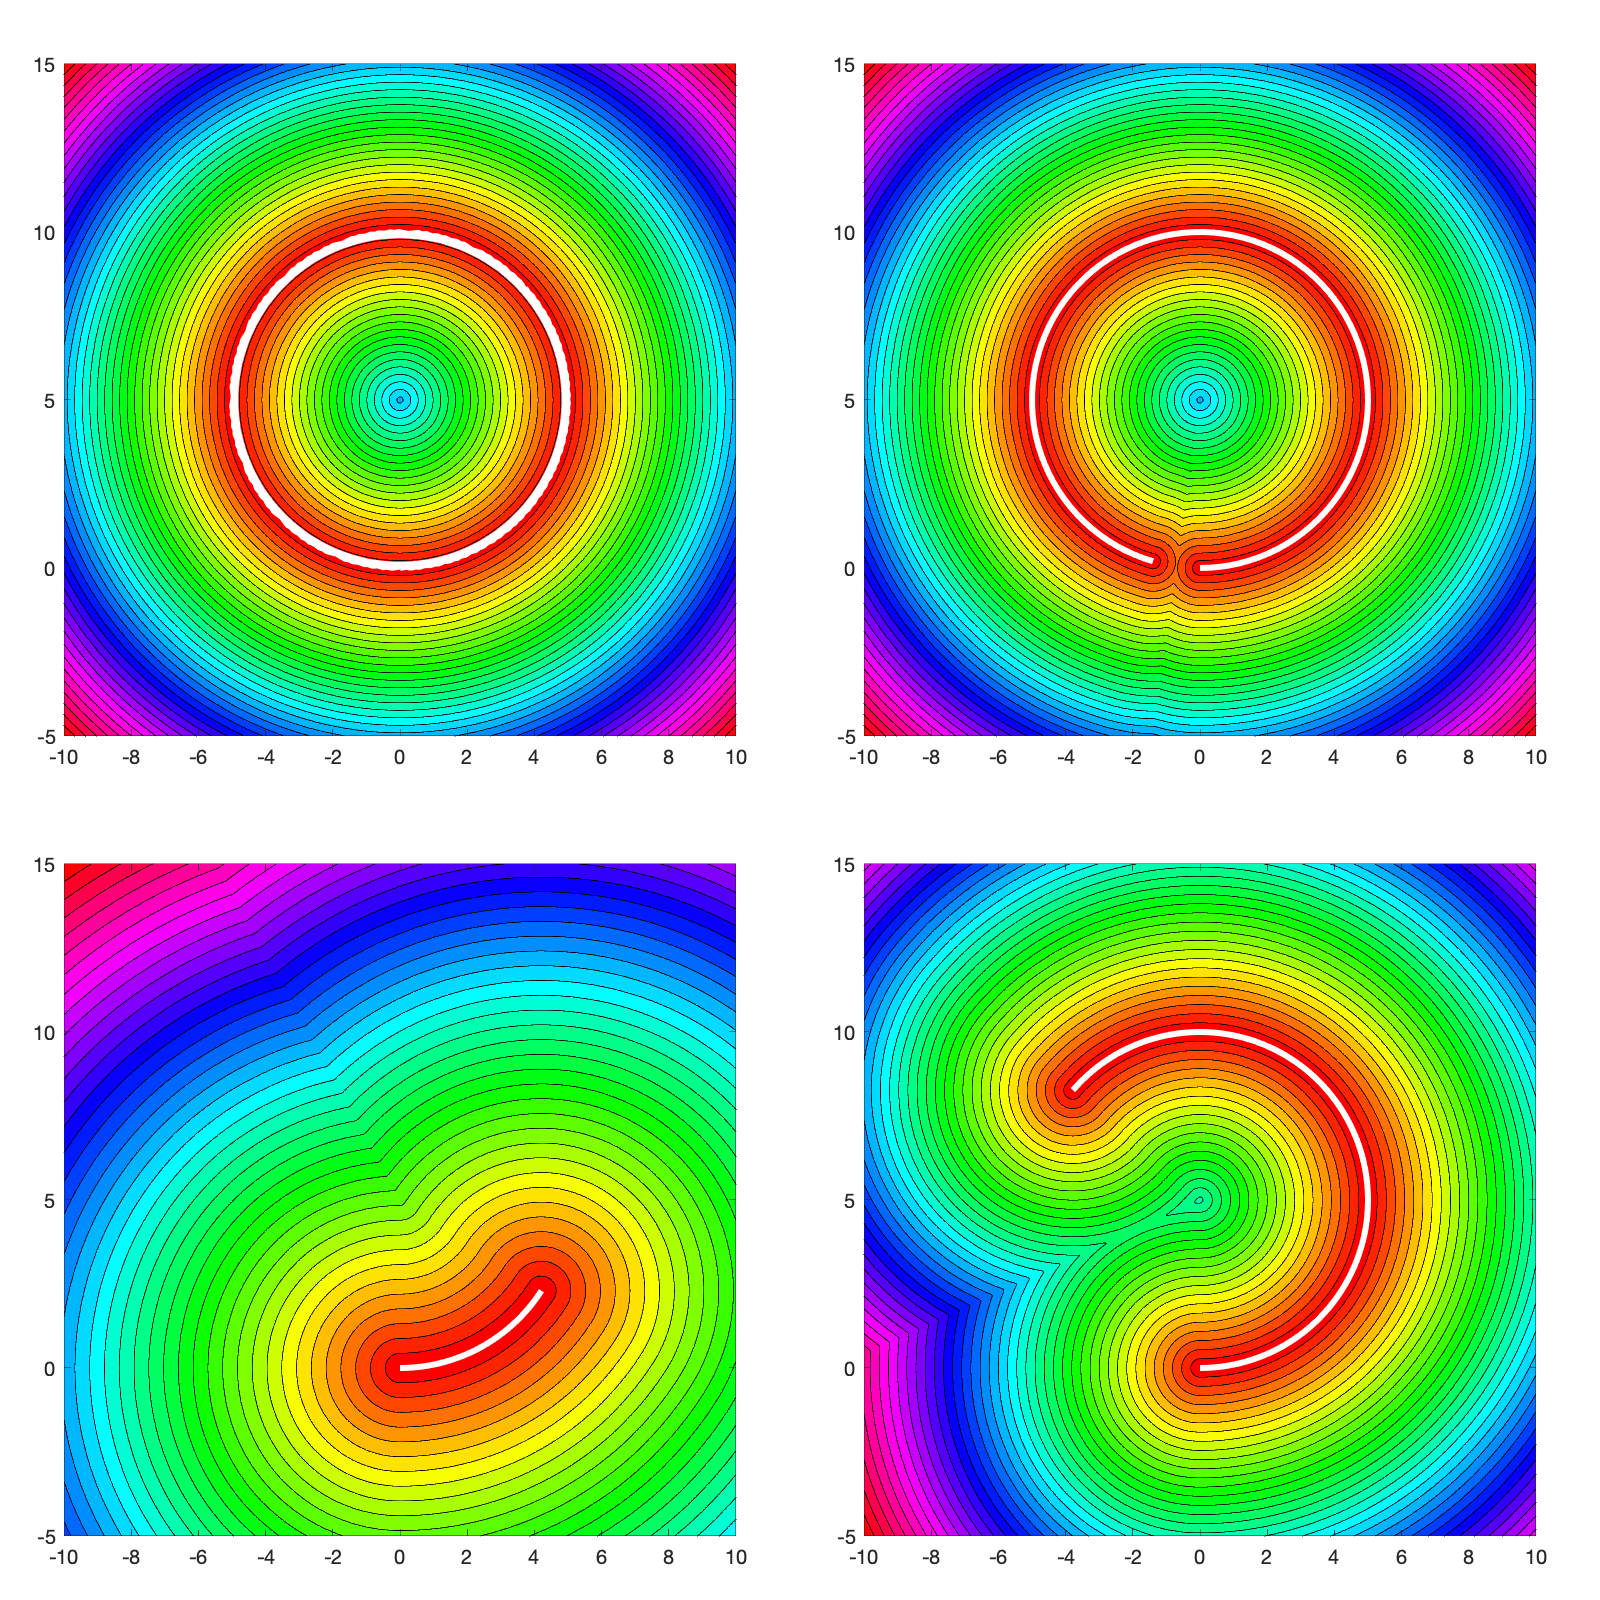

Elapsed time is 0.021172 seconds.


Elapsed time is 0.019003 seconds.


Elapsed time is 0.023872 seconds.


Elapsed time is 0.020651 seconds.


close all;

% check constructors
x0     = [0,0,0,0];
y0     = [0,0,0,0];
theta0 = 0;
kappa0 = [0.2, 0.2, 0.2, 0.2];
L      = [5,20,30,200];

aa = 0.04;
bb = 0.5-2*aa;

figure('Position',[ 1 1 800 800]);

for kk=1:4

  switch(kk)
  case 1; subplot('Position',[aa aa bb bb]);
  case 2; subplot('Position',[aa+0.5 aa bb bb]);
  case 3; subplot('Position',[aa+0.5 aa+0.5 bb bb]);
  case 4; subplot('Position',[aa aa+0.5 bb bb]);
  end

  %subplot(2,2,kk);
  L1 = CircleArc( x0(kk), y0(kk), theta0, kappa0(kk), L(kk) );
  %
  x     = -10:0.05:10;
  y     = -5:0.05:15;
  [X,Y] = meshgrid(x,y);

  tic
  Z = L1.distance(X,Y);
  toc
  %colormap(prism);
  colormap(hsv);
  contourf(X,Y,Z,40);
  %surf(X,Y,Z)
  axis equal;
  hold on;
  L1.plot(100,{'Color','White','Linewidth',3});
  %
  L1.delete();
end